clear;
set(0,'DefaultAxesFontName', 'Arial')
set(0,'DefaultAxesFontSize', 12)
f = 5e9; % 5 GHz
lam = freq2wavelen(f); % длина волны
% array params
xmtmin = -0;xmtmax = 12; % количество элементов
dOk = lam/2; % достаточное межэлементное расстояние
dNOk = lam/1.4; % увелчиенное
dSmooth = lam/32; % МЭ для сглаживания и визуализации

dxOk = dOk*(xmtmin:1:xmtmax)'; % координаты элементов
NNOk = ceil((max(dxOk)-min(dxOk))/dNOk); % число элементом разреженной решётки
Nsmooth = ceil((max(dxOk)-min(dxOk))/dSmooth);

dxNOk = linspace(min(dxOk),max(dxOk),NNOk)';
dxSmooth = linspace(min(dxOk),max(dxOk),Nsmooth)';


deltas = [0.9 2 1.1 1 ];
half = cumsum(deltas);
% max(half)+[fliplr(-half),0,half]
rare2 = dOk*(max(half)+[fliplr(-half),0,half])';
% rareSN = ceil((max(rare2)-min(rare2))/dSmooth); 
% rareS = linspace(min(rare2),max(rare2),rareSN)';
deltas = [0.9 1 1 1.1 1];
half = cumsum(deltas);
max(half)+[fliplr(-half),0,half]

ans =          0    1.0000    2.1000    3.1000    4.1000    5.0000    5.9000    6.9000    7.9000    9.0000   10.0000


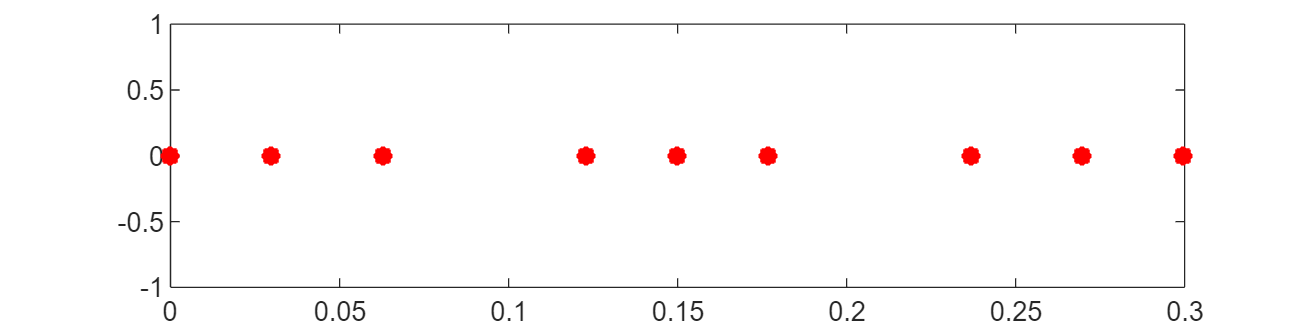

rare3 = dOk*(max(half)+[fliplr(-half),0,half])';


fig=figure;
plot(rare2,0*rare2,'r*','LineWidth',5)
fig.Position = [0 0 800 200];

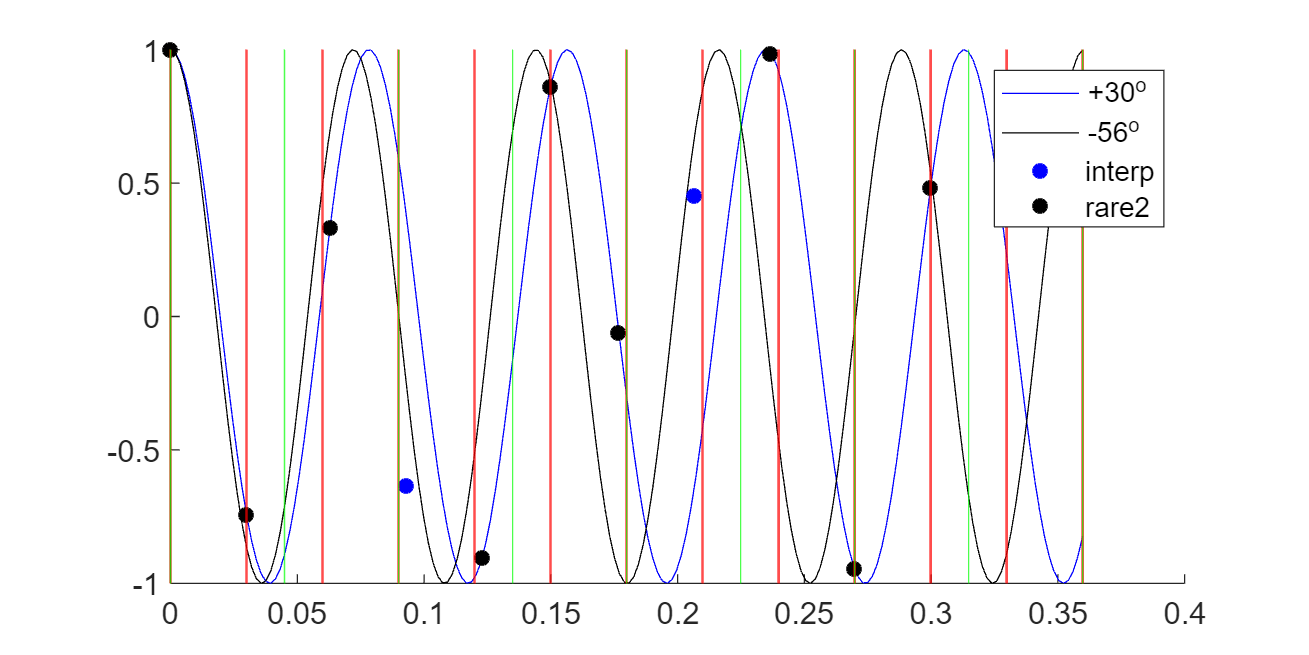



aimAngles = [50];
aimAmps   = [0]; %dB
resolution = 0.1; %deg

[valuesOk, phasesOk] = distribution_former(dxOk,f,aimAngles, aimAmps);
[valuesNOk, phasesNOk] = distribution_former(dxNOk,f,aimAngles, aimAmps);
[valuesSmooth, phasesSmooth] = distribution_former(dxSmooth,f,aimAngles, aimAmps);
[valS2,phs2] = distribution_former(dxSmooth,f,[-56.3], [0]);
valuesRare = distribution_former(rare2,f,aimAngles, aimAmps);


% rareSN = ceil((max(rare2)-min(rare2))/dOk);
% rareS = linspace(min(rare2),max(rare2),rareSN)';
valuesRare2 = interp1(rare2,valuesRare,rare3,"spline");
% valuesRare2(end-1:end) = [];
rare22 = rare3;
% rare22(end-1:end) = [];



fig=figure; hold on;
fig.Position = [50 200 800 400];
plot(dxSmooth,real(valuesSmooth),'b-')
% plot(dxOk,real(valuesOk),'r*','LineWidth',0.5)
% plot(dxNOk,real(valuesNOk),'g*','LineWidth',1)
plot(dxSmooth,real(valS2),'k-','LineWidth',0.5)
plot(rare22,real(valuesRare2),'b*','LineWidth',2)
plot(rare2,real(valuesRare),'k*','LineWidth',2)
xline(dxOk,'r-','LineWidth',1)
xline(dxNOk,'g-')
% legend('','\lambda/2','\lambda/1.4')
% legend('+30^o','\lambda/2','\lambda/1.4','-56^o')
legend('+30^o','-56^o','interp','rare2')

% % % % 
% valuesOk = valuesOk.*chebwin(length(valuesOk),40);

disp("equidistant array")

equidistant array


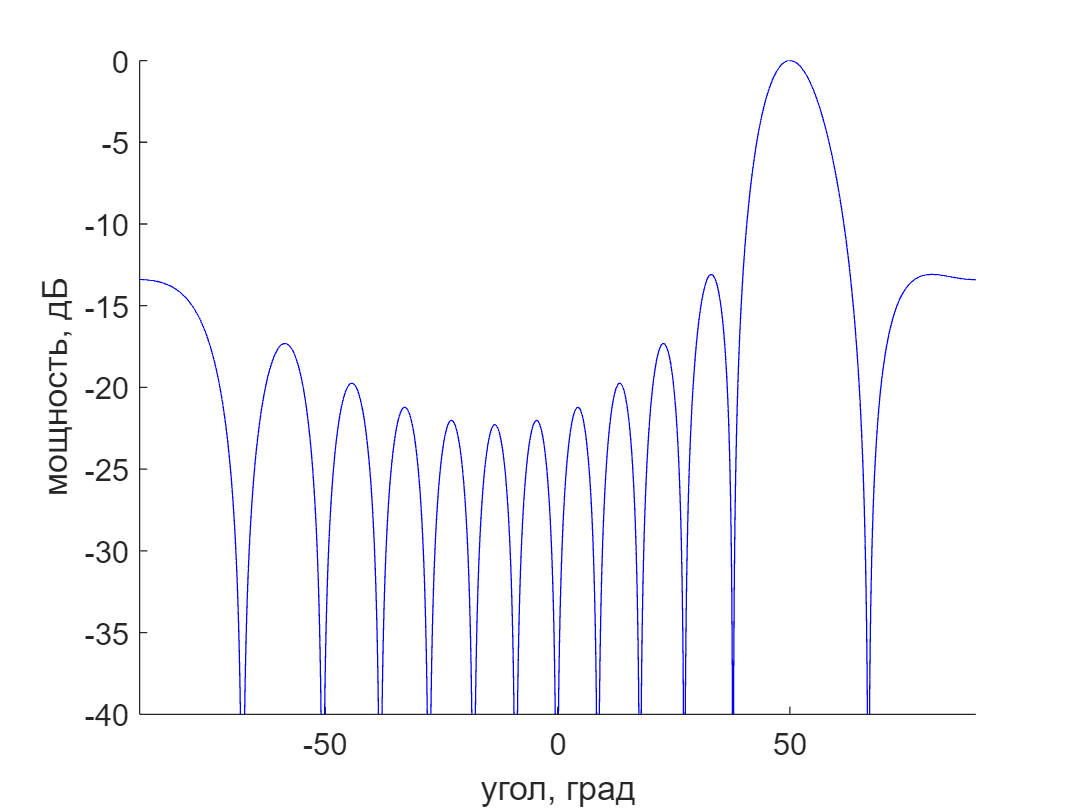

[rstOk,theta] = aec_simulation(valuesOk, dxOk,f,resolution);
rstOkT = mag2db(abs(rstOk));rstOkT = rstOkT - max(rstOkT);
figure; hold on
plot(theta, rstOkT,'b');
xlabel("угол, град")
ylabel("мощность, дБ")
% title("equidistant array")
axis([-90 90 -40 0])


disp("rared array")

rared array


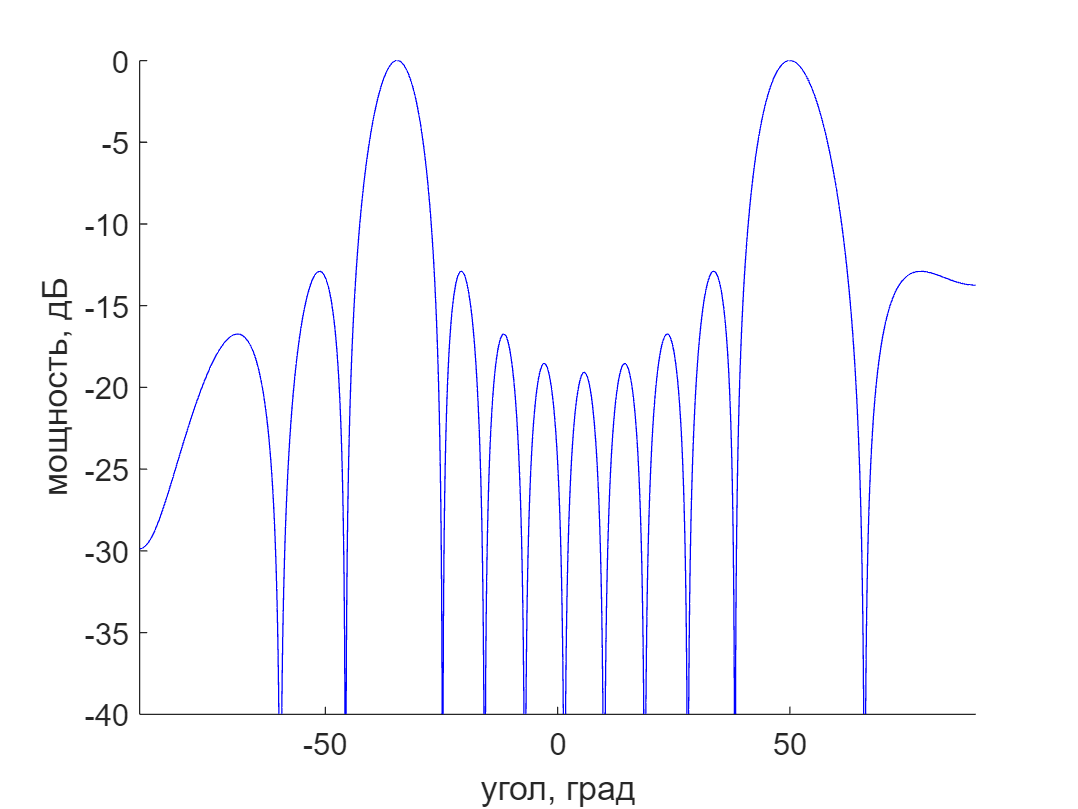

[rstOk,theta] = aec_simulation(valuesNOk, dxNOk,f,resolution);
rstOkT = mag2db(abs(rstOk));rstOkT = rstOkT - max(rstOkT);
figure; hold on
plot(theta, rstOkT,'b');
xlabel("угол, град")
ylabel("мощность, дБ")
% title("rared array")
axis([-90 90 -40 0])



disp("my rare")

my rare


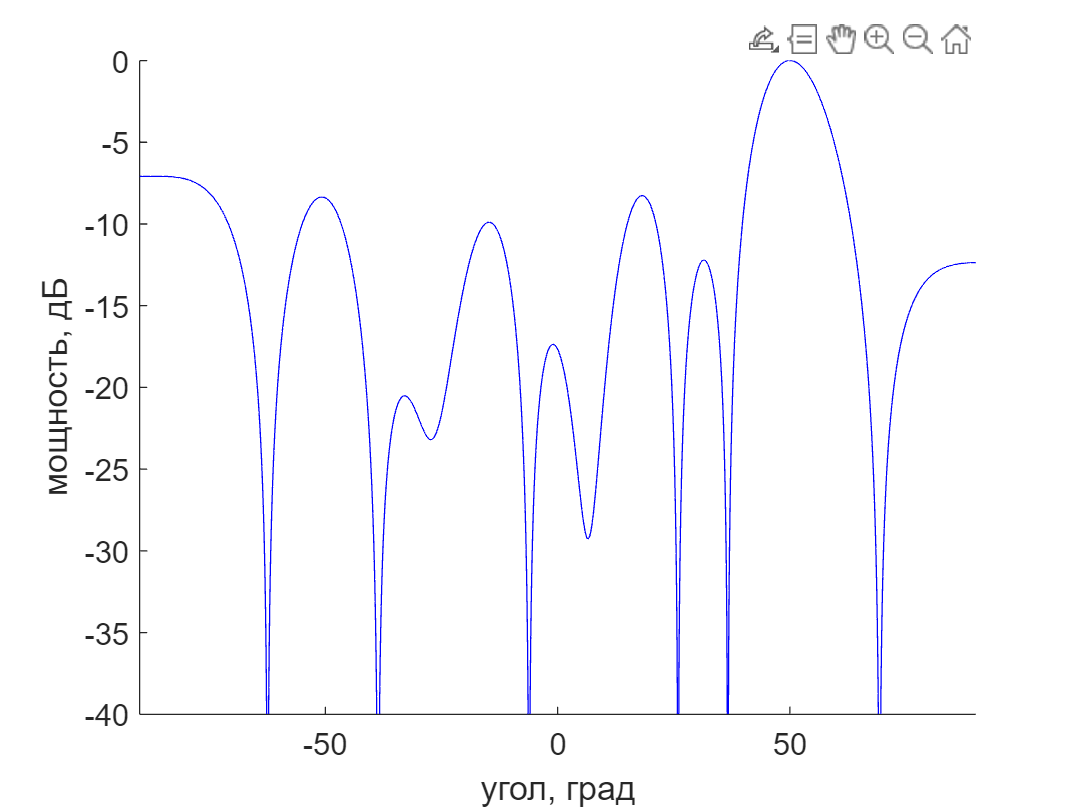

[rstOk,theta] = aec_simulation(valuesRare, rare2,f,resolution);
rstOkT = mag2db(abs(rstOk));rstOkT = rstOkT - max(rstOkT);
figure; hold on
plot(theta, rstOkT,'b');
xlabel("угол, град")
ylabel("мощность, дБ")
% title("my rare")
axis([-90 90 -40 0])



% valuesRare = valuesRare.*(0.1 + chebwin(length(valuesRare),60));
disp("interp rare")

interp rare


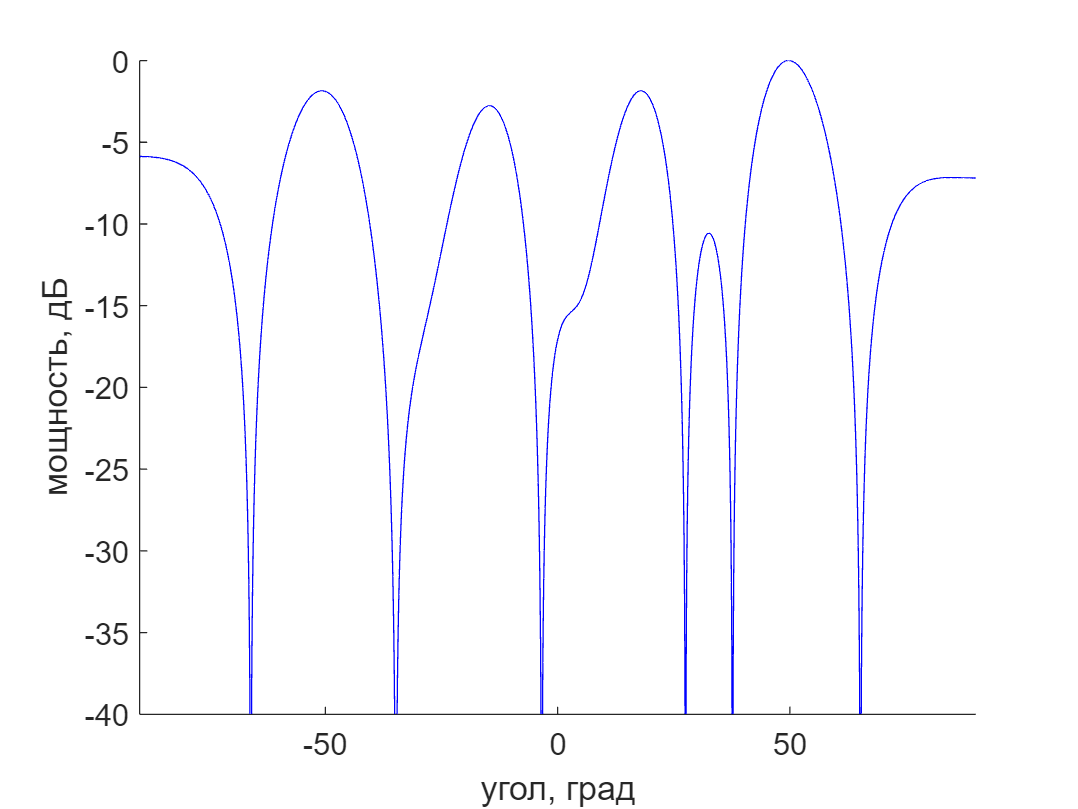

[rstOk,theta] = aec_simulation(valuesRare2, rare22,f,resolution);
rstOkT = mag2db(abs(rstOk));rstOkT = rstOkT - max(rstOkT);
figure; hold on
plot(theta, rstOkT,'b');
xlabel("угол, град")
ylabel("мощность, дБ")
% title("interp rare")
axis([-90 90 -40 0])